# Week 2 Numerical Integration

**Written by:        **Caiden Bonney

**Created:            **1/28/25

**Modified:          ** 1/28/25

**Background:     **

This lab introduces the concept of Numerical Integration in which derivatives are approximated using an integration step size, Δt, where a smaller step size increases the accuracy. To practice Numerical Integration this lab calculates the position and velocity in the x and y directions for a falling object disregarding air resistance and a skydiver with a parachute. The specific Numerical Integration method used is Euler's Forward Integration Method to approximate the integrals of acceleration to find velocity and position. The acceleration equation is based on the forces acting upon the object such as gravity and drag force in the case of the skydiver after deploying their parachute. 

**Required File:**

- ME326_05_Activity2_BonneyCaiden_MatLabFile

## Problem Statement

To illustrate the use of Numerical Integration, specifically Euler's Forward Integration Method, the position and velocity of a falling object and a skydiver with a parachute are modeled in Tasks 1 through 3.

## 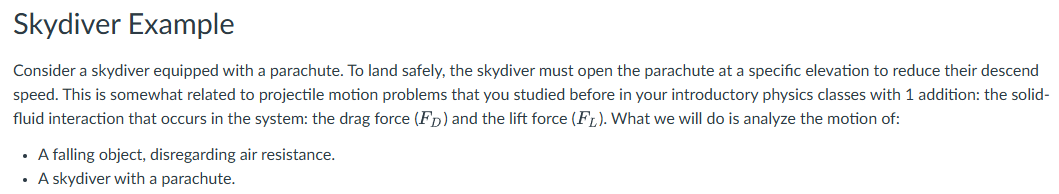

Task 1 is solved through general integration with initial conditions modeling a falling object disregarding air resistance this is solved by hand in the Hand Calculations section. Task 2 Models Task 1 using Euler's Forward Integration Method to approximate the general integration used in Task 1. Task 3 follows the same setup as Task 2 for a skydiver with a parachute, however, after the parachute is deployed the acceleration of the skydiver is no longer constant which must be accounted for. A depiction of the forces acting upon the skydiver once the parachute is deployed is depicted below to illustrate how the drag forces always act in opposition to any motion.  

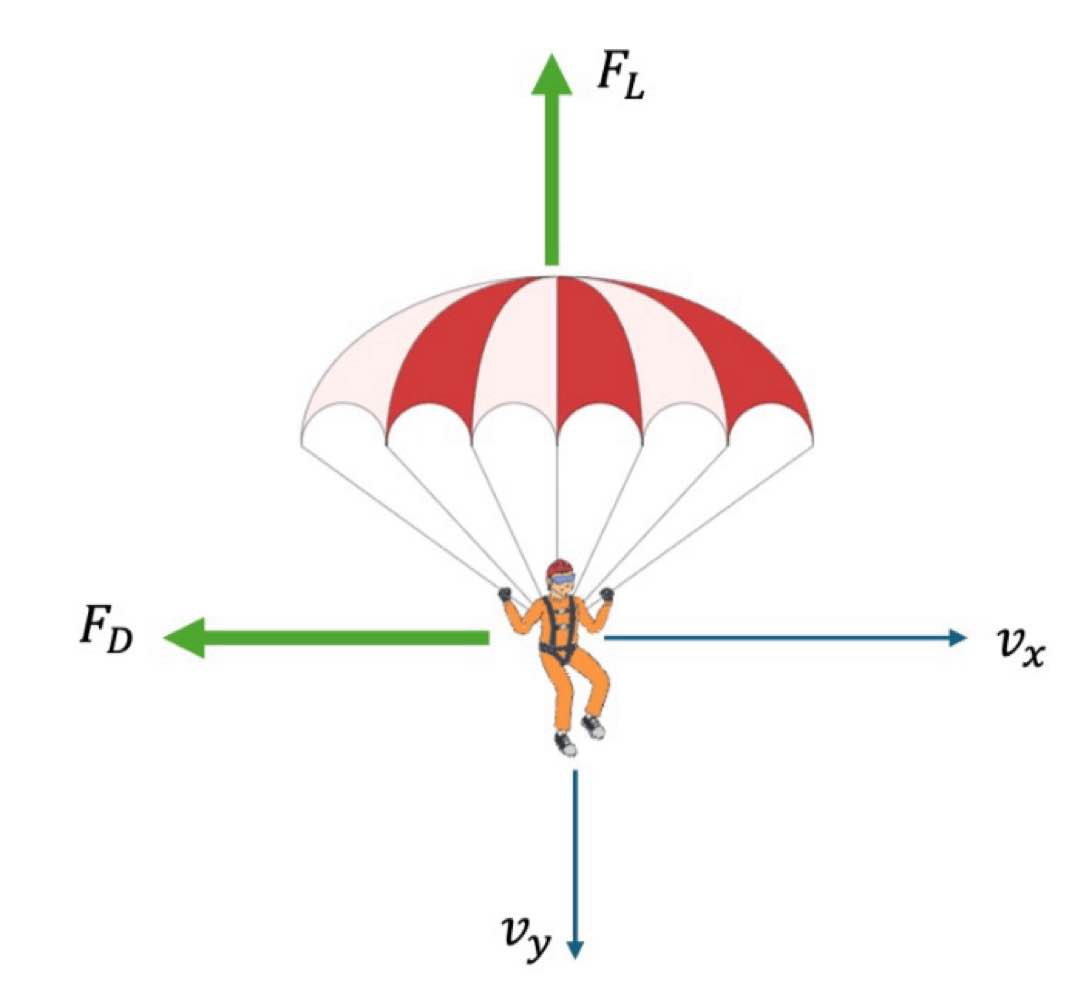

## Hand Calculations

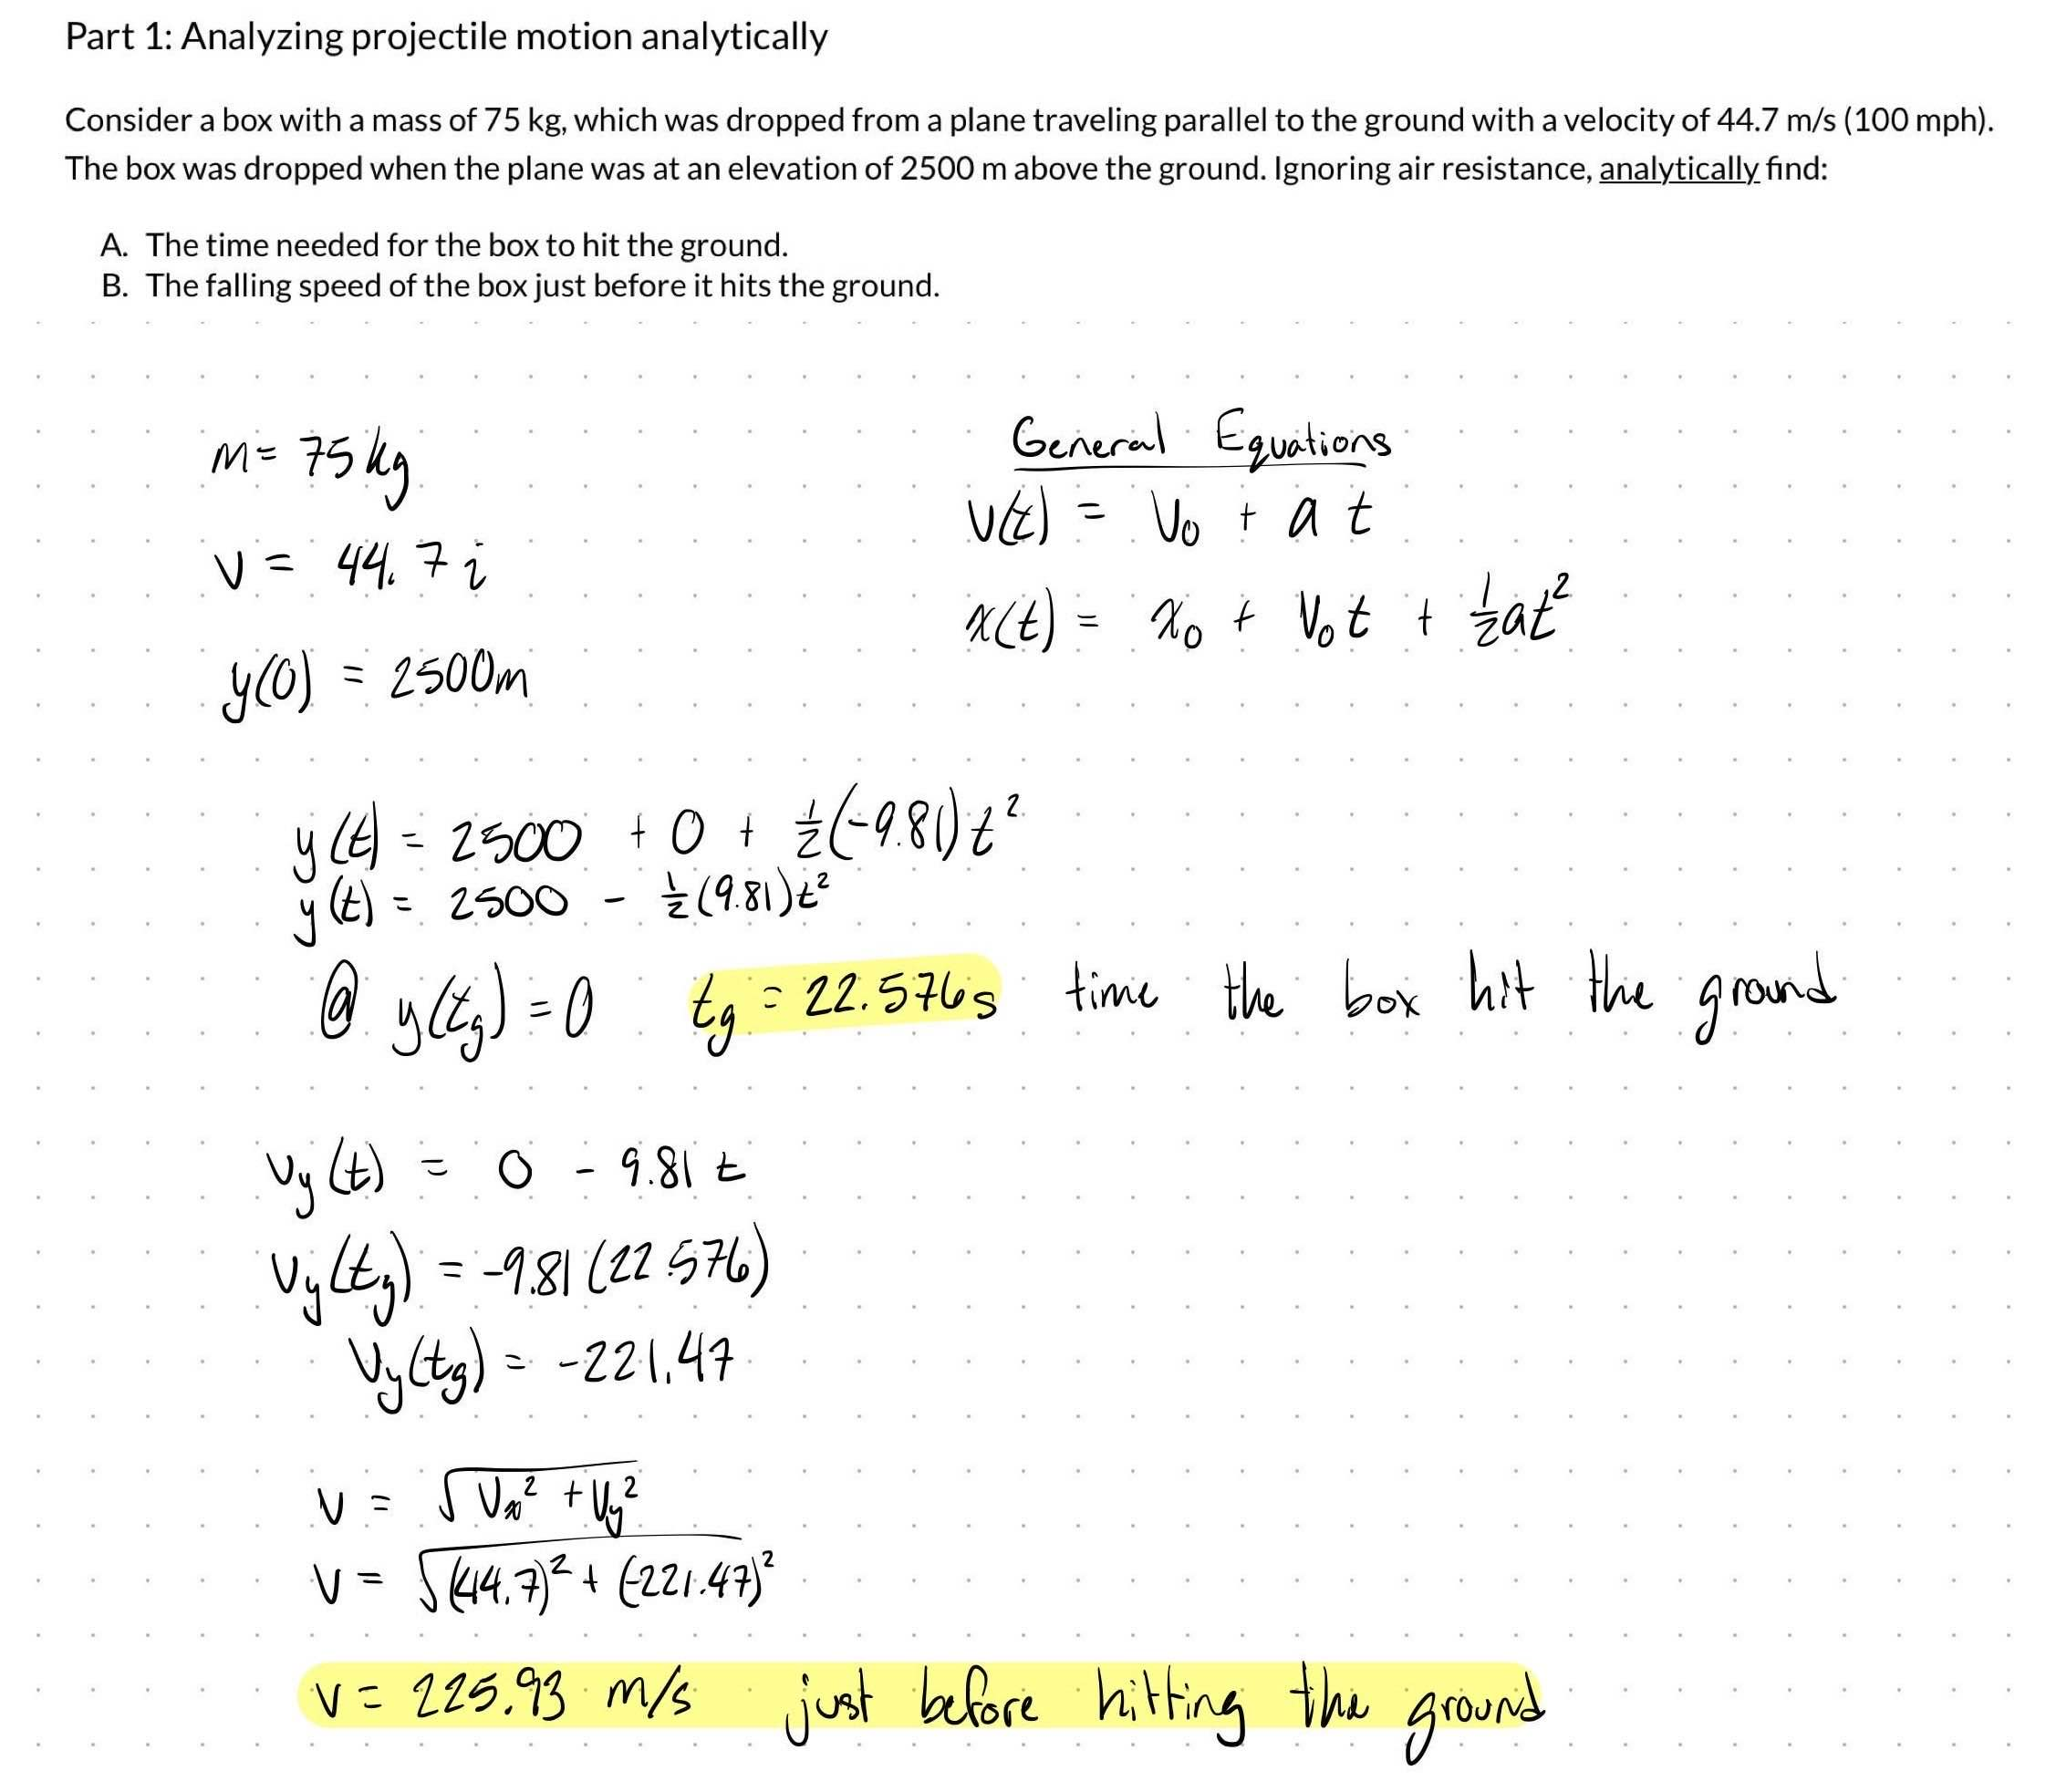

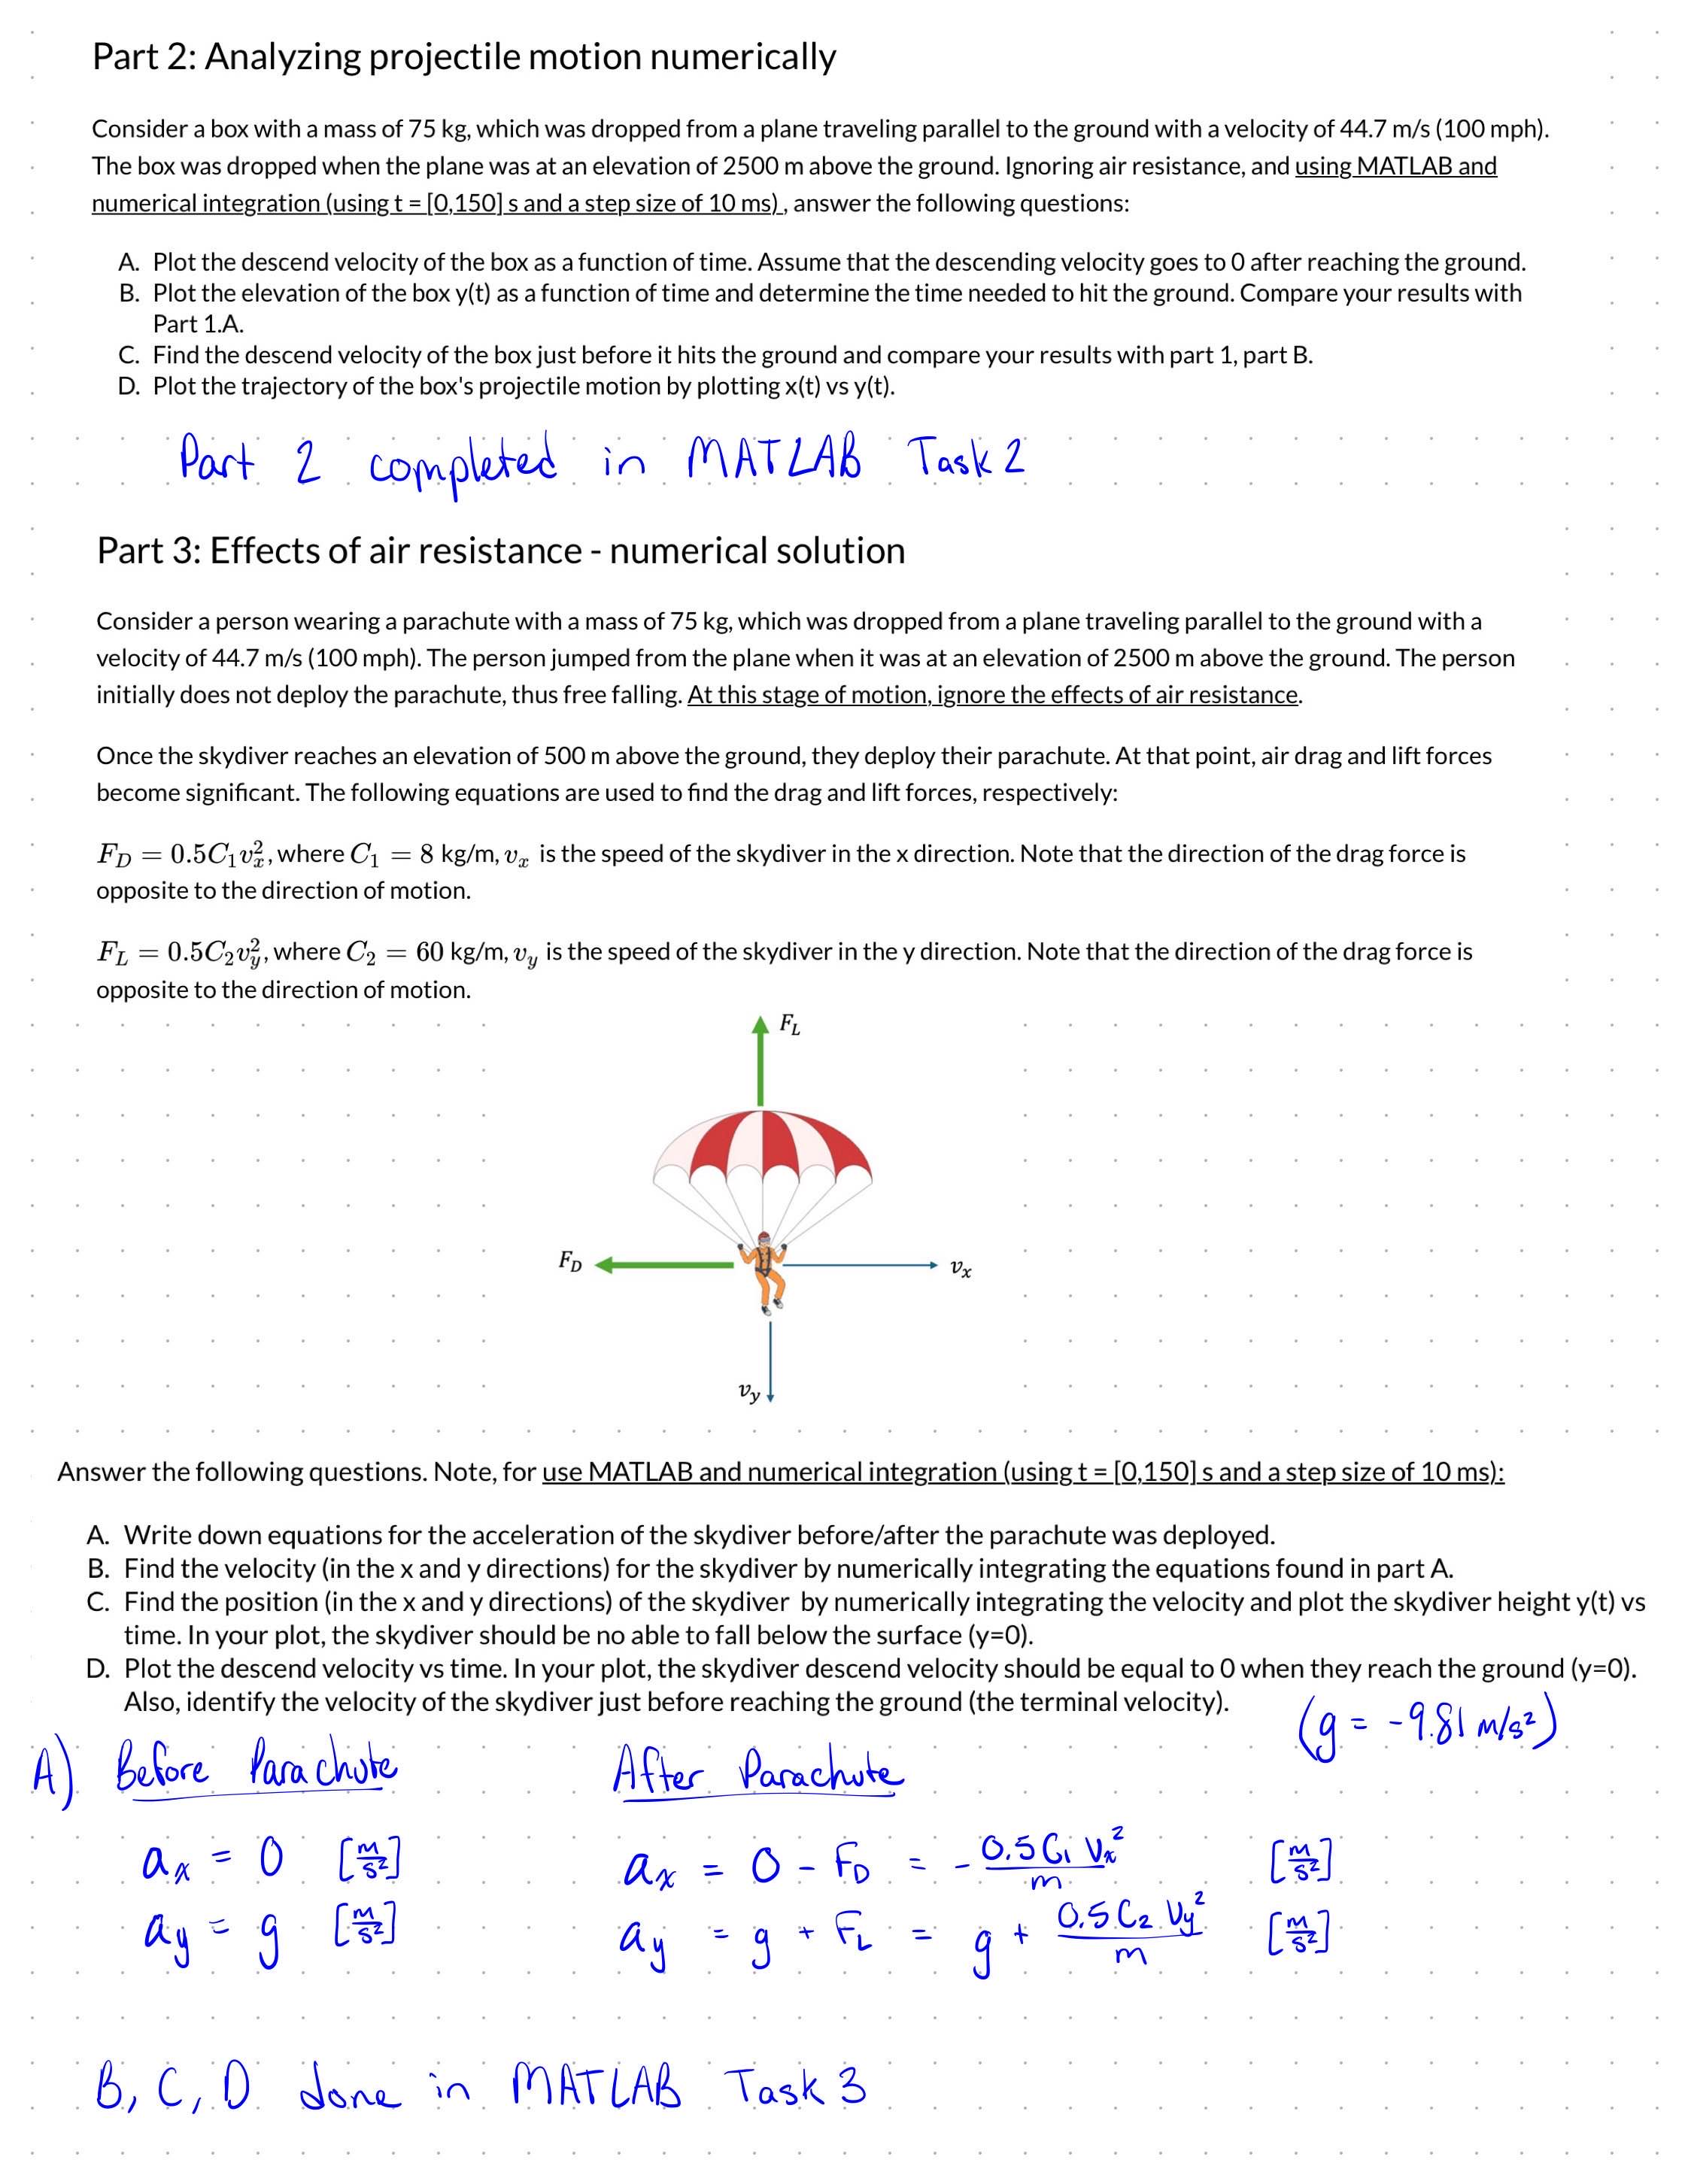

## Preliminary Analysis

clear
clc

%%% Setup. The following variables will be used throughout the code

m = 75; %mass of the box or skydiver (kg)
C1 = 8; %coefficient of drag force
C2 = 60; %coefficient of lift force
v0 = [44.7, 0]; %velocity vector in x and y (m/s)
g = -9.81; %gravitational acceleration (m/s^2)
y0 = 2500; %Initial elevation (m)
x0 = 0; %Initial horizontal position (m)

dt = 0.01; %Numerical integration step size

t = 0:dt:150;  %Time array

## Task 2: Numerical Methods

After setting the initial values of the velocity and initializing the position in both coordinates a for loop iterates through the matrix t which counts from 0 to 150 seconds in steps of dt. For each element in t, the velocities and positions in both x and y are calculated and added to the end of the existing velocity and position matrixes. For each iteration of the loop, the matrixes grew by one element. Because the initial values were already set before the for loop, it only needs to run for the length of t - 1 or until the box hits the ground at which point the for loop will be broken with the break statement at the end.

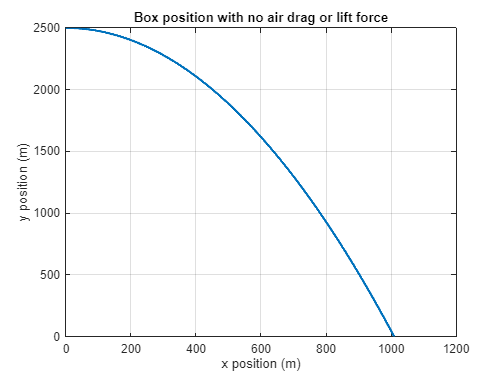

vx(1) = v0(1); %Initial x velocity
vy(1) = v0(2); %Initial y velocity

x(1) = x0; %Initial x position
y(1) = y0; %Initial y position

for i=1:length(t)-1
    vy(i+1) = vy(i)+g*dt; %Velocity in the y direction in the next time step
    vx(i+1) = vx(i); %Velocity in the x direction in the next time step
    x(i+1) = x(i)+vx(i)*dt; %Position in the x direction in the next time step
    y(i+1) = y(i)+vy(i)*dt+0.5*g*(dt^2); %%Position in the y direction in the next time step
    if y(i+1) <= 0
        y(i+1) = 0; %Sets position to ground level
        vy(i+1) = 0; %Sets vertical velocity to 0
        break;
    end
end

figure(1)
plot(x,y, LineWidth=2) %plot trajectory of falling y vs x
xlabel 'x position (m)'
ylabel 'y position (m)'
title 'Box position with no air drag or lift force'
grid on

The plot depicts the box's vertical position against its horizontal position. This represents what the box's path looked like as it fell from the plane from a static outside observer. After the box's vertical position reaches zero, its y position and velocity are set to zero since it has hit the ground, and the simulation is stopped. 

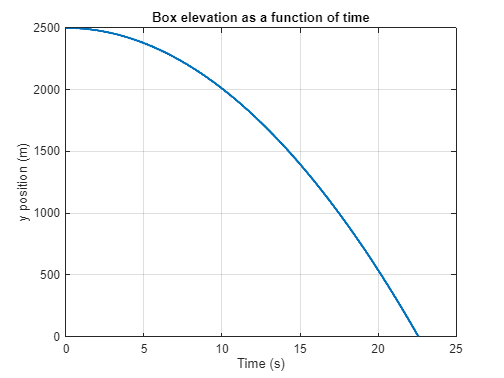

figure(2)
plot(t(1:length(y)),y, LineWidth=2) %plot the elevation of the box as a function of time
xlabel 'Time (s)'
ylabel 'y position (m)'
title 'Box elevation as a function of time'
grid on

The plot depicts the box's vertical position over time, with the instantaneous slope representing its vertical velocity. The time at which the y position first reaches 0 is the time at which the box hits the ground. 

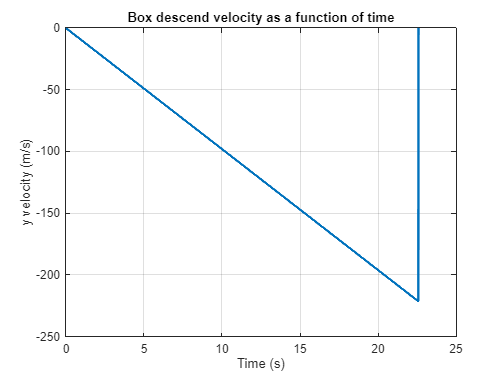

figure(3)
plot(t(1:length(vy)),vy, LineWidth=2) %plot the descend velocity of the box as a function of time
xlabel 'Time (s)'
ylabel 'y velocity (m/s)'
title 'Box descend velocity as a function of time'
grid on

The plot depicts the vertical velocity of the box over time where the instantaneous slope represents the acceleration of the box vertically. The acceleration is the gravitational constant g for the whole length of the fall leading to the straight line shown. The vertical velocity increases in magnitude until it reaches the time at which the box hits the ground at which point it is reset back to zero.

v = sqrt(vx.^2 + vy.^2);
[max_speed, t_idx_impact] = max(v); %max speed the box reached the fall
t_impact = t(t_idx_impact) %time of impact (s)

t_impact = 22.5700

max_speed %final speed just before impact (m/s)

max_speed = 225.8788

The velocity and speed are very close to the hand calculations however there are slight inaccuracies due to the resolution of the time step dt. Decreasing dt further would increase the accuracy of these calculations. 

## Task 3: Including Air Resistance

After setting the initial values of the velocity and initializing the position in both coordinates a for loop iterates through the matrix t which counts from 0 to 150 seconds in steps of dt. At 500 m the skydiver opens their parachute at which point drag forces need to be accounted for. These drag forces are converted into their effect on the acceleration of the skydiver by dividing the force by the skydiver's mass. These effects on acceleration are then added to the current acceleration in that direction which is 0 for x and the gravitational constant g for y. For each element in t the velocities and positions in both directions are calculated using the current acceleration in that direction then the result is added as the next element in the matrix. Due to the initial values already being set the for loop only iterates through the length of t -1 or until the skydiver reaches the ground at which point there is no need for the simulation to continue to run so the for loop breaks.  

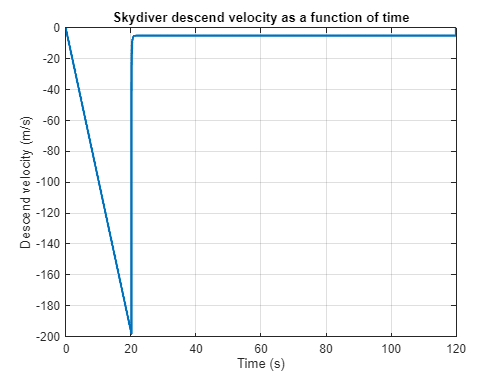

%With air drag and lift force
%Note: x_with_air is a vector with information about x(t) for task 3
%(skydiver)

x_with_air(1) = x0; %Initial x position
y_with_air(1) = y0; %Initial y position

vx_with_air = v0(1); %Initial x velocity
vy_with_air = v0(2);  %Initial y velocity

y_parachute_open = 500; %Elevation when the parachute deploys

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i = 1:length(t)-1
    if y_with_air(i) <= y_parachute_open
        %Drag forces after parachute deployment
        F_D = 0.5*C1*vx_with_air(i)^2; %Drag Force for this time step
        F_L = 0.5*C2*vy_with_air(i)^2; %Lift Force for this time step
    else 
        %Drag forces before parachute deployment
        F_D = 0; %Drag Force is 0 before the parachute deploys
        F_L = 0; %Lift Force is 0 before the parachute deploys
    end 

        %Note that the acceleration is no longer constant and will vary with
        %the drag forces acting upon it. 

    %Acceleration Calculations
    ax_with_air = -F_D/m;
    ay_with_air = g + F_L/m;

    %Velocity Calculations
    vx_with_air(i+1) = vx_with_air(i) + ax_with_air*dt;
    vy_with_air(i+1) = vy_with_air(i) + ay_with_air*dt;

    %Position Calculations
    x_with_air(i+1) = x_with_air(i) + vx_with_air(i)*dt + 0.5*ax_with_air*(dt^2);
    y_with_air(i+1) = y_with_air(i) + vy_with_air(i)*dt + 0.5*ay_with_air*(dt^2);

    %Updates velocities and positions once the skydiver reaches the ground
    if y_with_air(i+1) <= 0
        y_with_air(i+1) = 0; %Sets position to ground level
        vy_with_air(i+1) = 0; %Sets vertical velocity to 0
        break;
    end
end 

v_with_air = sqrt(vx_with_air.^2 + vy_with_air.^2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(4)
plot(t(1:length(vy_with_air)),vy_with_air, LineWidth=2) %plot the descend velocity of the skydiver as a function of time
xlabel 'Time (s)'
ylabel 'Descend velocity (m/s)'
title 'Skydiver descend velocity as a function of time'
grid on

The plot depicts the vertical velocity of the skydiver over time where the instantaneous slope represents the acceleration of the skydiver vertically. The acceleration is the gravitational constant g until the skydiver releases their parachute at 500m above the ground at which point drag force is taken into account. The drag force is based on the vertical velocity of the skydiver and as a result, the change in velocity is not instantaneous like it is when the skydiver reaches the ground. After a short period, the vertical velocity reaches terminal velocity leading to the portion of the graph past roughly 22 seconds into the fall. 

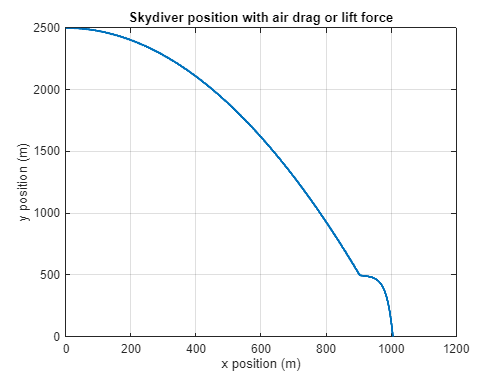

figure(5)
plot(x_with_air,y_with_air, LineWidth=2) %plot the trajectory of the skydiver as a function of time
xlabel 'x position (m)'
ylabel 'y position (m)'
title 'Skydiver position with air drag or lift force'
grid on

The plot depicts the position of the skydiver from an outside perspective as they falls both vertically and horizontally. Before the parachute is deployed the graph matches that of Task 1 and 2 where the drag force from the air is negligible, however, once the skydiver reaches 500 m and is deployed the parachute drag forces are no longer negligible, and slow the fall both vertically and horizontally. 

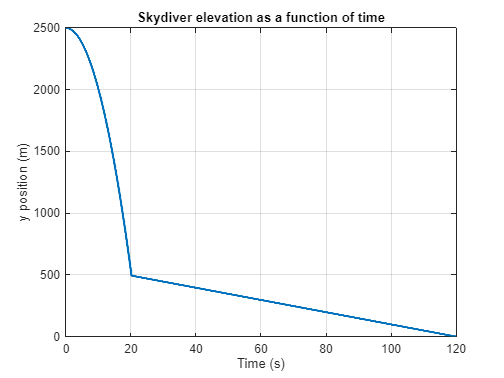

figure(6)
plot(t(1:length(y_with_air)),y_with_air, LineWidth=2) %plot the elevation of the skydiver as a function of time
xlabel 'Time (s)'
ylabel 'y position (m)'
title 'Skydiver elevation as a function of time'
grid on

The plot depicts the vertical position of the skydiver over the course of the fall. Before the parachute was deployed a parabolic arc was drawn as the skydiver fell. The parachute deployed at 500 m quickly slowing the skydiver until they reached terminal velocity in the vertical direction. Terminal velocity is the speed at which the drag force cancels out with gravity leading to an acceleration of zero in that direction. This is denoted in the graph by the constant slope during the later half of the fall for the vertical velocity. 

t_idx_impact_with_air = find(y_with_air==0,1) - 1; %index just before the skydiver touches the ground at y_with_air = 0 
impact_speed_with_air = v_with_air(t_idx_impact_with_air);
t_impact_with_air = t(t_idx_impact_with_air) %time of impact (s)

t_impact_with_air = 119.9200

vy_impact_with_air = vy_with_air(t_idx_impact_with_air) %velocity in the y direction just before the skydiver touches the ground (m/s)

vy_impact_with_air = -4.9523

vx_impact_with_air = vx_with_air(t_idx_impact_with_air) %velocity in the x direction just before the skydiver touches the ground (m/s)

vx_impact_with_air = 0.1871

impact_speed_with_air %final speed just before the skydiver touches the ground (m/s)

impact_speed_with_air = 4.9558

The skydiver never reached true terminal velocity as the horizontal component never completely canceled out during the fall. However, the skydiver's final speed is represented by impact_speed_with_air above in m/s.